# How-to add ions to a simulation box

Add ions randomly wherever there is space (this function is similar to `solvate_atom()` and `insert_atom()`

Box_dim=[30 30 30];
Cation='Na'

Cation = 'Na'

nCation=20;
System=[];
%% atom = create_atom(type,resname,limits,scale,maxion,in_atom)
Ion1 = create_atom(Cation,Cation,[0 0 0 Box_dim(1) Box_dim(2) Box_dim(3)],nCation/2,2,System);

Atom_label = 1×1 cell array
    {'Na'}

ans =    250

Box_dim_temp =    3.960000000000000   3.960000000000000   3.960000000000000


add2atom done!
x - dim


ans =      8

y - dim


ans =     64

z - dim


ans =    512

nAtom before merge


ans =    512

nIon after merge


ans =     10

Choose between these representations:
ballstick licorice smallvdw halfvdw vdw contour crystal ionic polyhedra lines labels charge index


rmaxlong =    2.250000000000000

Calculating the distance matrix


ans = 1×1 cell array
    {'Na'}

ans =     10

Elapsed time is 0.165681 seconds.
Drawing the atoms
Elapsed time is 0.004143 seconds.
Elapsed time is 0.000029 seconds.


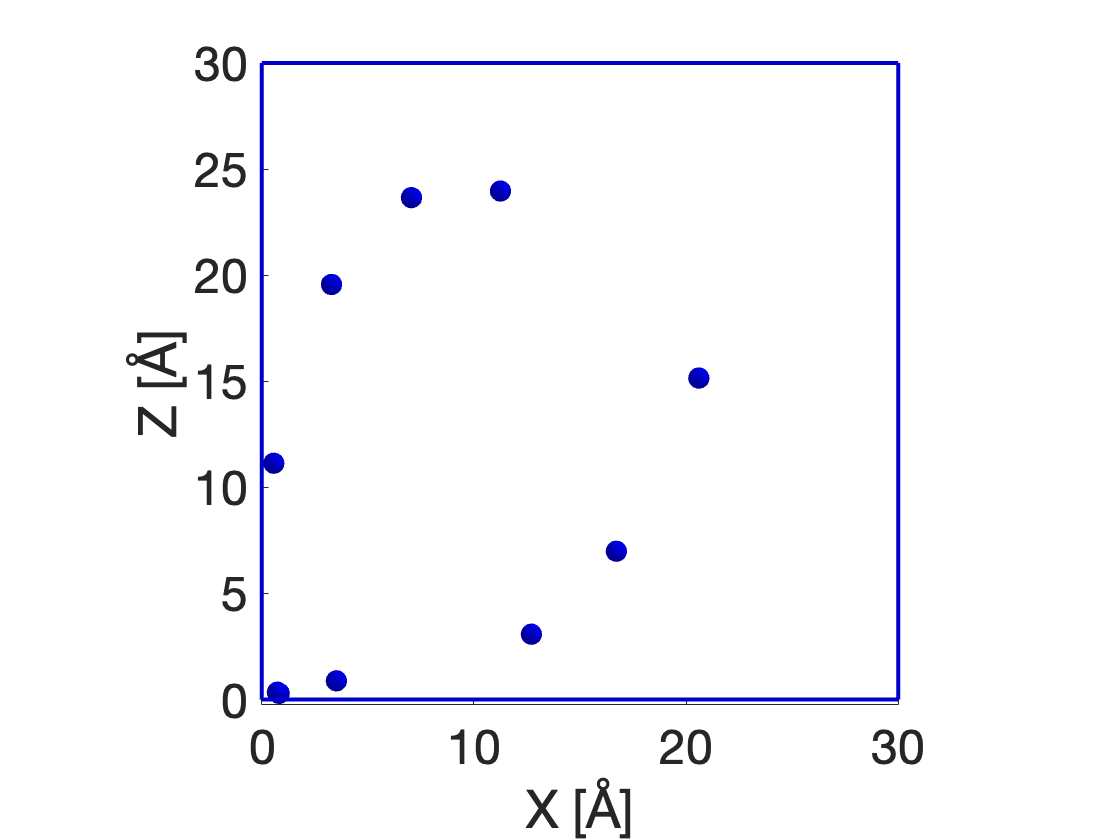

% vmd(Ion,Box_dim)
show_atom(Ion1,Box_dim)


%% Add ions using the copy_atom function
%% atom = copy_atom(atom,origtype,newtype,newresname,trans_vec,num);
Ion2 = copy_type(MMT,'Mgo',Cation,Cation,[0 0 8],sum(ismember([MMT.type],'Mgo'))/2);



Ion3 = create_grid_atom('Na',nCatIonblk/planes,'Cl',0,[Box_dim(1) Box_dim(2) 95+i*8],'xy');
